### ProbCond

- Wykresy poprawy

- Histogramy

- Tabela zestawieniowa

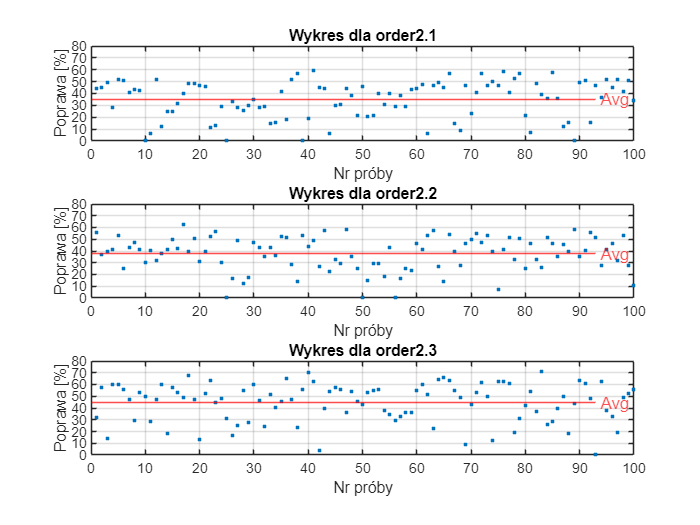

clear all; %#ok<CLALL>
load("results.mat")

ord_2_1_rel_imp = problemConditioningData(problemConditioningData.ExperimentName == 2.1, {'RelativeImprovement'});
ord_2_2_rel_imp = problemConditioningData(problemConditioningData.ExperimentName == 2.2, {'RelativeImprovement'});
ord_2_3_rel_imp = problemConditioningData(problemConditioningData.ExperimentName == 2.3, {'RelativeImprovement'});

ord_2_1_rel_imp.RelativeImprovement = ord_2_1_rel_imp.RelativeImprovement * 100;
ord_2_2_rel_imp.RelativeImprovement = ord_2_2_rel_imp.RelativeImprovement * 100;
ord_2_3_rel_imp.RelativeImprovement = ord_2_3_rel_imp.RelativeImprovement * 100;


ord_2_1_rel_imp_avg = mean(ord_2_1_rel_imp.RelativeImprovement);
ord_2_2_rel_imp_avg = mean(ord_2_2_rel_imp.RelativeImprovement);
ord_2_3_rel_imp_avg = mean(ord_2_3_rel_imp.RelativeImprovement);

ord_2_1_rel_imp_std = std(ord_2_1_rel_imp.RelativeImprovement);
ord_2_2_rel_imp_std = std(ord_2_2_rel_imp.RelativeImprovement);
ord_2_3_rel_imp_std = std(ord_2_3_rel_imp.RelativeImprovement);

prob_cond_names = [string(1.1); string(1.2); string(1.3);];
prob_cond_avgs = [ord_2_1_rel_imp_avg; ord_2_2_rel_imp_avg; ord_2_3_rel_imp_avg];
prob_cond_stds = [ord_2_1_rel_imp_std; ord_2_2_rel_imp_std; ord_2_3_rel_imp_std];

prob_cond_comparison = table(prob_cond_names, prob_cond_avgs, prob_cond_stds, 'VariableNames', {'Order', 'avg', 'std'});

max_value = max([max(ord_2_1_rel_imp.RelativeImprovement), ...
    max(ord_2_2_rel_imp.RelativeImprovement), ...
    max(ord_2_3_rel_imp.RelativeImprovement)]);
y_axis_limit_plot = ceil(max_value / 10) * 10;

bin_width = 5;
max_count_2_1 = max(histcounts(ord_2_1_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_2_2 = max(histcounts(ord_2_2_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_2_3 = max(histcounts(ord_2_3_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
y_axis_limit_hist = max([max_count_2_1, max_count_2_2, max_count_2_3]) + 10;

figure;

subplot(3, 1, 1);
plot(ord_2_1_rel_imp.RelativeImprovement, '.');
yline(ord_2_1_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla order2.1');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(3, 1, 2);
plot(ord_2_2_rel_imp.RelativeImprovement, '.');
yline(ord_2_2_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla order2.2');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(3, 1, 3);
plot(ord_2_3_rel_imp.RelativeImprovement, '.');
yline(ord_2_3_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla order2.3');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

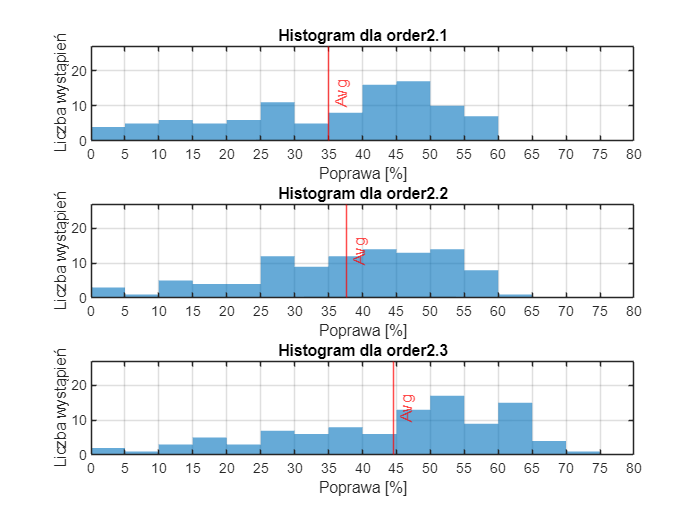


figure;

% Histogram dla ord_2_1_rel_imp
subplot(3, 1, 1);
histogram(ord_2_1_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(ord_2_1_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla order2.1');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla ord_2_2_rel_imp
subplot(3, 1, 2);
histogram(ord_2_2_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(ord_2_2_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla order2.2');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla ord_2_3_rel_imp
subplot(3, 1, 3);
histogram(ord_2_3_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(ord_2_3_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla order2.3');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);


prob_cond_comparison

prob_cond_comparison = 3×3 table
    Order     avg       std  
    _____    ______    ______

    "1.1"    35.022    15.849
    "1.2"    37.633    14.346
    "1.3"    44.621    16.237
